realText  = fileread("chp13.txt");

% Load stopwords.
filename = "stopwords.txt";
str = extractFileText(filename);
customStopWords =  union(stopWords,split(str,newline)');

cleanedDocument = tokenizedDocument(realText);
cleanedDocument = removeStopWords(cleanedDocument);
cleanedDocument = removeWords(cleanedDocument, customStopWords);
cleanedDocument = normalizeWords(cleanedDocument);
cleanedDocument = erasePunctuation(cleanedDocument);
cleanedDocument = removeShortWords(cleanedDocument,2);
cleanedDocument = removeLongWords(cleanedDocument,15);

% Get unique tokens:
wordsTok = string(cleanedDocument);
wordsTok = unique(wordsTok);

% Remove numbers:
filteredWords = "";
wordCounter = 1;
for i = 1:length(wordsTok)
    charArr = convertStringsToChars(wordsTok(1,i));
    isLetterArr = isletter(wordsTok(1,i));
    a = isLetterArr(1);
    if(a == 1)
        filteredWords(wordCounter,1) = wordsTok(1,i);
        wordCounter = wordCounter + 1;
    end
end

filteredWords;

% Get stemmed sentences:
sentences = split(realText,[".","!","?"]);
cleanedSentences = tokenizedDocument(sentences);
cleanedSentences = normalizeWords(cleanedSentences);
cleanedSentences = erasePunctuation(cleanedSentences);
cleanedSentences = removeShortWords(cleanedSentences,2);
cleanedSentences = removeEmptyDocuments(cleanedSentences);
stemmedSentences = string(joinWords(cleanedSentences(:,1)));



% Make the TSM:
TSM = zeros(length(filteredWords),length(stemmedSentences));
for i = 1:length(filteredWords)
    for j = 1:length(stemmedSentences)
        TSM(i,j) = length(find(split(stemmedSentences(j), " ") == filteredWords(i)));
    end
end
TSM;

clf
format long

% Calculate the tf-idf:
weightedData = zeros(length(filteredWords),length(stemmedSentences));
N = length(stemmedSentences);
for term = 1:length(filteredWords)
    df = 0;
    for sentence = 1:length(stemmedSentences)
        
        % Sum of how many times the term found in all the sentences:
        if(find(split(stemmedSentences(sentence), " ") == filteredWords(term)))
            df = df + 1;
        end
        
    end
    
    for sentence = 1:length(stemmedSentences)
        % Sum of how many times the terms occurs in sentence j:
        tf = TSM(term,sentence);
        
        weightedData(term,sentence) = tf * log((N/df)); 
    end

         
end
weightedData(isnan(weightedData))=0;


% Make SVD matrix:
[u, s ,v] = svds(weightedData,1);


k=10;
% Get k most important terms:
[termValue,termIndex] = maxk(u,k);
filteredWords(termIndex(:))

ans = 10×1 string array
    "page"
    "rank"
    "outlink"
    "search"
    "web"
    "correspond"
    "follow"
    "element"
    "equal"
    "matrix"





% Get k most important sentences:
[sentenceValue,sentenceIndex] = maxk(v,k);
string(sentences(sentenceIndex(:)))

ans = 10×1 string array
    " ↵↵Define if there is a link from to, otherwise"
    " ↵↵However, a ranking system based only on the number of inlinks is easy to manipulate:30 whenyoudesignaWebpageithat (e"
    " ↵↵An acceleration method based on Aitken extrapolation is described in [65]"
    "↵↵A Google search with the same search phrase made on February 6, 2019, gave the top result University - Wikipedia, which is a good answer for the highly underspecified search phrase"
    " ↵↵Let Q be a square matrix of dimension n"
    "↵↵A Google search conducted on September 29, 2005, using the search phrase university, gave as a result links to the following well-known universities: Harvard, Stanford, Cambridge, Yale, Cornell, Oxford"
    " ↵↵In [63] an adaptive method is described that checks the convergence of the components of the pagerank vector and avoids performing the power iteration for those components"
    " Loosely speaking, Google assigned a high rank to a Web page if it had inlinks 

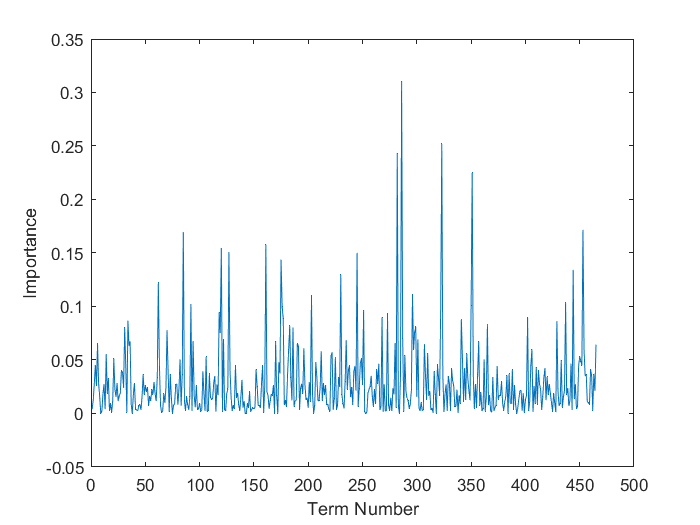

 

% Plot results:
plot(1:length(u), u(:,1))
xlabel("Term Number")
ylabel("Importance")

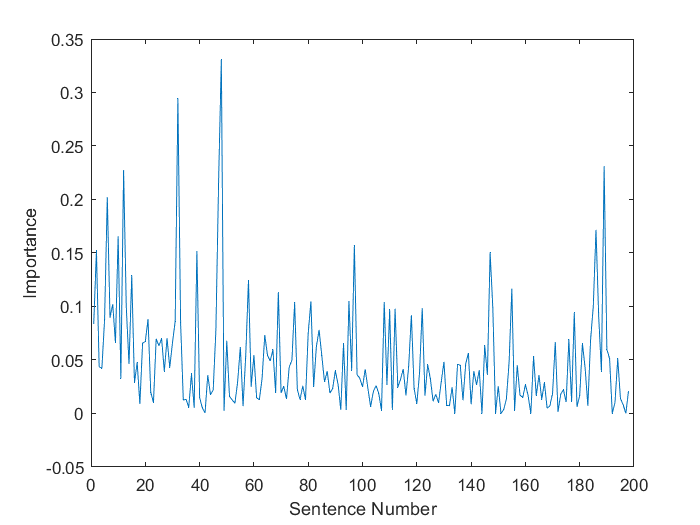


plot(1:length(v), v)
xlabel("Sentence Number")
ylabel("Importance")


idx = rank_k(weightedData,k);
sentences(idx)

ans = 10×1 cell array
    {' ↵↵Define if there is a link from to, otherwise'                                                                                                                                                            }
    {'↵↵When a search is made on the Internet using a search engine, there is first a traditional text processing part, where the aim is to find all the Web pages containing the words of the query'             }
    {' ↵↵Due to the massive size of the Web, the number of hits is likely to be much too large to be of use'                                                                                                      }
    {' ↵↵Therefore, some measure of quality is needed to filter out pages that are assumed to be less interesting'                                                                                                }
    {'↵↵When one uses a Web search engine it is typical that the search phrase is underspecified'                                 

string(sentences(sentenceIndex(:)))

ans = 10×1 string array
    " ↵↵Define if there is a link from to, otherwise"
    " ↵↵However, a ranking system based only on the number of inlinks is easy to manipulate:30 whenyoudesignaWebpageithat (e"
    " ↵↵An acceleration method based on Aitken extrapolation is described in [65]"
    "↵↵A Google search with the same search phrase made on February 6, 2019, gave the top result University - Wikipedia, which is a good answer for the highly underspecified search phrase"
    " ↵↵Let Q be a square matrix of dimension n"
    "↵↵A Google search conducted on September 29, 2005, using the search phrase university, gave as a result links to the following well-known universities: Harvard, Stanford, Cambridge, Yale, Cornell, Oxford"
    " ↵↵In [63] an adaptive method is described that checks the convergence of the components of the pagerank vector and avoids performing the power iteration for those components"
    " Loosely speaking, Google assigned a high rank to a Web page if it had inlinks 

function [res] = rank_k(TSM,k)
%Rank-k approximation
[U ,S, V] = svds(TSM,k);
D = S(1,1:k)*V(:,1:k)'; 
[Q,RS,P] = qr(D);

n = length(P(1,:));
p=(1:n)*P;
pk = p(1:k);
res = pk;

end